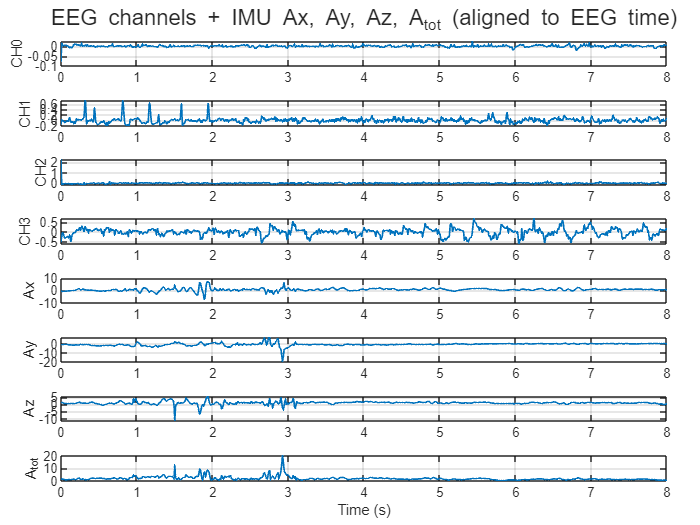

clear; close all; clc

% ---------- Load EEG ----------
S = load("week04_only.mat");
x_fn    = S.x_fn;
earData = S.earData;

fs = earData.sampleRate;

sec = 8;
M   = min(size(x_fn,2), round(sec*fs));
t   = (0:M-1)/fs;

numCh = size(x_fn,1);

% ---------- Load IMU CSV ----------
T = readtable("2025.08.27.16.23.20_Rec_3+4.csv");

vars = string(T.Properties.VariableNames);
ix = find(contains(lower(vars), "ax") | contains(lower(vars), "accx"), 1);
iy = find(contains(lower(vars), "ay") | contains(lower(vars), "accy"), 1);
iz = find(contains(lower(vars), "az") | contains(lower(vars), "accz"), 1);
it = find(contains(lower(vars), "time") | strcmpi(vars, "t"), 1);

tcsv = [];
if ~isempty(ix) && ~isempty(iy) && ~isempty(iz)
    ax = T{:, ix}; ay = T{:, iy}; az = T{:, iz};
else
    X = table2array(T);
    X = X(:, all(isfinite(X),1));
    if size(X,2) >= 4
        tcsv = X(:,1); ax = X(:,2); ay = X(:,3); az = X(:,4);
    elseif size(X,2) >= 3
        ax = X(:,1); ay = X(:,2); az = X(:,3);
    else
        error("Could not find Ax/Ay/Az in the CSV (check delimiter/columns).");
    end
end

if isempty(tcsv)
    if ~isempty(it)
        tcsv = T{:, it};
    else
        tcsv = (0:numel(ax)-1);
    end
end

ax = ax(:); ay = ay(:); az = az(:); tcsv = tcsv(:);

% If tcsv is sample index, convert to seconds (set fs_csv correctly)
if all(mod(tcsv,1)==0) && (max(tcsv) > 2) && (max(tcsv) > 5) && (max(tcsv) > 10)
    fs_csv = 100;          % <-- set IMU sampling rate if tcsv isn't seconds
    tcsv   = tcsv / fs_csv;
end

A_total = sqrt(ax.^2 + ay.^2 + az.^2);

% ---------- Interpolate IMU onto EEG timebase ----------
ax_i = interp1(tcsv, ax,      t, "linear", "extrap");
ay_i = interp1(tcsv, ay,      t, "linear", "extrap");
az_i = interp1(tcsv, az,      t, "linear", "extrap");
At_i = interp1(tcsv, A_total, t, "linear", "extrap");

% ---------- Plot: EEG + IMU ----------
figure("Color","w","Name","EEG + IMU (Ax Ay Az Atotal)");
tl = tiledlayout(numCh+4, 1, "TileSpacing","compact", "Padding","compact");

for ch = 1:numCh
    nexttile
    plot(t, x_fn(ch,1:M), "LineWidth", 1); grid on
    ylabel("CH" + (ch-1))
end

nexttile
plot(t, ax_i, "LineWidth", 1); grid on
ylabel("Ax")

nexttile
plot(t, ay_i, "LineWidth", 1); grid on
ylabel("Ay")

nexttile
plot(t, az_i, "LineWidth", 1); grid on
ylabel("Az")

nexttile
plot(t, At_i, "LineWidth", 1); grid on
ylabel("A_{tot}")
xlabel("Time (s)")

title(tl, "EEG channels + IMU Ax, Ay, Az, A_{tot} (aligned to EEG time)")

mu_eeg = mean(x_fn(:,1:M), 2, "omitnan");
mu_imu = mean([ax_i(:) ay_i(:) az_i(:) At_i(:)], 1, "omitnan");

fprintf("EEG mean (first %d samples):\n", M);

EEG mean (first 80000 samples):


for ch = 1:numel(mu_eeg)
    fprintf("  CH%d: %.6g\n", ch-1, mu_eeg(ch));
end

  CH0: 4.36717e-05
  CH1: 0.00111968
  CH2: -0.00167544
  CH3: 0.000771934


fprintf("IMU mean (first %d samples):\n", M);

IMU mean (first 80000 samples):


fprintf("  Ax: %.6g\n  Ay: %.6g\n  Az: %.6g\n  Atot: %.6g\n", mu_imu);

  Ax: 0.672942
  Ay: -0.510515
  Az: 0.920956
  Atot: 2.03772


% EEG: zero-mean per channel (use same M window)
mu_eeg = mean(x_fn(:,1:M), 2, "omitnan");
x0    = x_fn(:,1:M) - mu_eeg;

% IMU: zero-mean per axis (use same M window)
mu_imu = mean([ax_i(:) ay_i(:) az_i(:) At_i(:)], 1, "omitnan");
ax0 = ax_i(:) - mu_imu(1);
ay0 = ay_i(:) - mu_imu(2);
az0 = az_i(:) - mu_imu(3);
At0 = At_i(:) - mu_imu(4);




fprintf("fs=%.3f, M=%d, size(x_fn)=[%d %d]\n", fs, M, size(x_fn,1), size(x_fn,2));

fs=10000.000, M=80000, size(x_fn)=[4 656148]


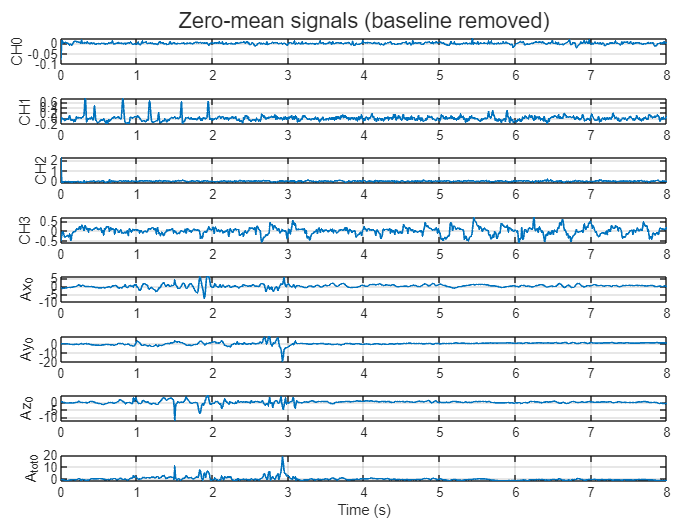

figure("Color","w","Name","Zero-mean EEG + IMU");
tl = tiledlayout(numCh+4, 1, "TileSpacing","compact", "Padding","compact");

for ch = 1:numCh
    nexttile
    plot(t, x0(ch,:), "LineWidth", 1); grid on
    ylabel("CH" + (ch-1))
end

nexttile
plot(t, ax0, "LineWidth", 1); grid on
ylabel("Ax_0")

nexttile
plot(t, ay0, "LineWidth", 1); grid on
ylabel("Ay_0")

nexttile
plot(t, az0, "LineWidth", 1); grid on
ylabel("Az_0")

nexttile
plot(t, At0, "LineWidth", 1); grid on
ylabel("A_{tot0}")
xlabel("Time (s)")

title(tl, "Zero-mean signals (baseline removed)")

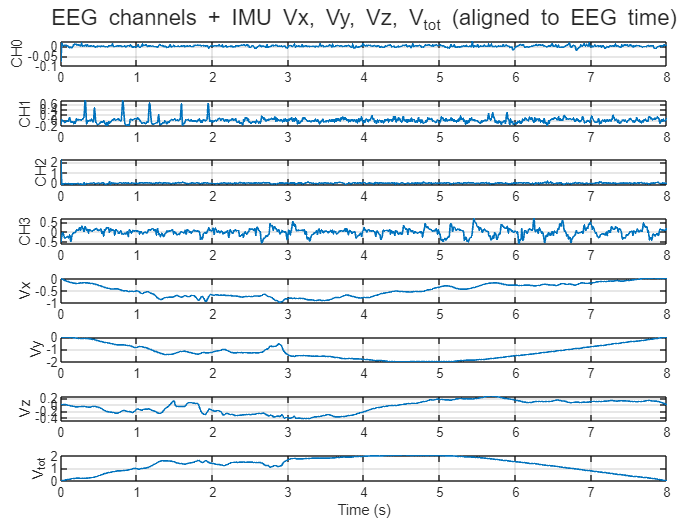

vx = cumtrapz(t(:), ax0);
vy = cumtrapz(t(:), ay0);
vz = cumtrapz(t(:), az0);
vTot = sqrt(vx.^2 + vy.^2 + vz.^2);

% --- Plot: EEG + IMU velocity ---
figure("Color","w","Name","EEG + IMU (Velocity)");
tl = tiledlayout(numCh+4, 1, "TileSpacing","compact", "Padding","compact");

for ch = 1:numCh
    nexttile
    plot(t, x_fn(ch,1:M), "LineWidth", 1); grid on
    ylabel("CH" + (ch-1))
end

nexttile
plot(t, vx, "LineWidth", 1); grid on
ylabel("Vx")

nexttile
plot(t, vy, "LineWidth", 1); grid on
ylabel("Vy")

nexttile
plot(t, vz, "LineWidth", 1); grid on
ylabel("Vz")

nexttile
plot(t, vTot, "LineWidth", 1); grid on
ylabel("V_{tot}")
xlabel("Time (s)")

title(tl, "EEG channels + IMU Vx, Vy, Vz, V_{tot} (aligned to EEG time)")

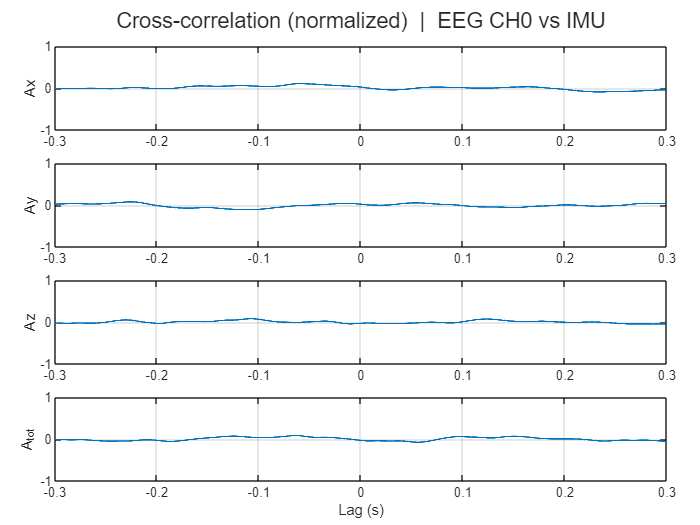

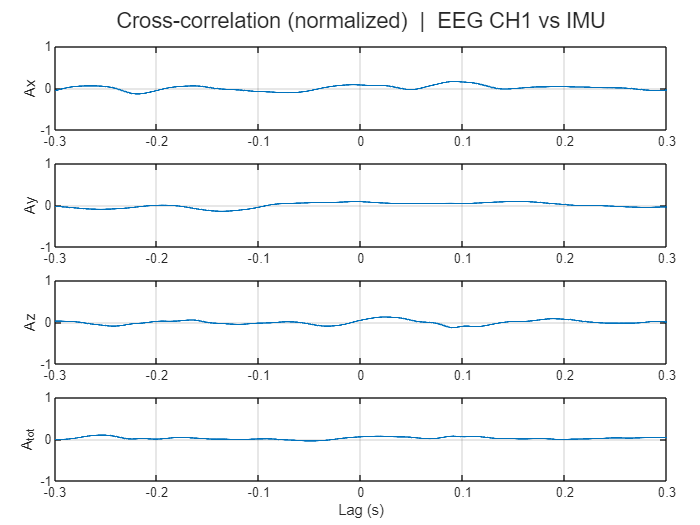

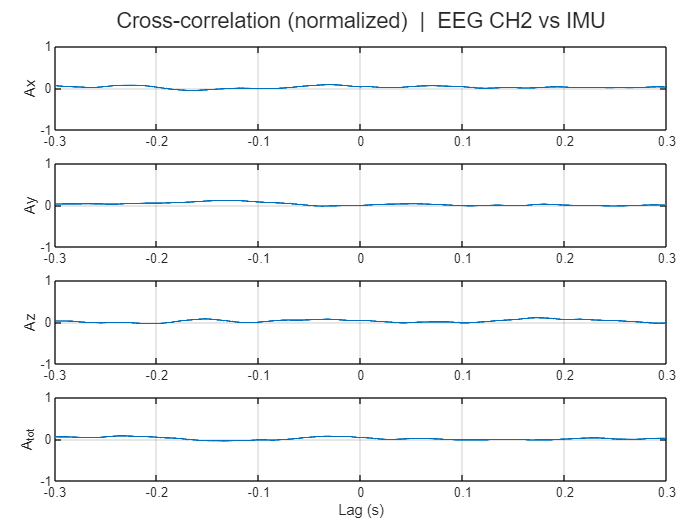

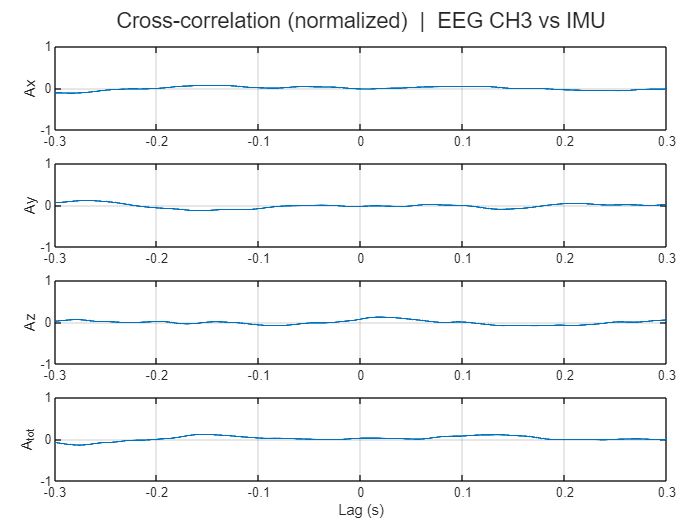

imuNames = ["Ax","Ay","Az","A_{tot}"];
imuSig   = [ax0(:) ay0(:) az0(:) At0(:)];     % [M x 4]

maxLagSec = 0.3;
L = round(maxLagSec * fs);

for ch = 1:4
    x = double(x0(ch,:)).';
    x = x - mean(x, "omitnan");

    figure("Color","w","Name", "CH" + (ch-1) + " vs IMU xcorr");
    tl = tiledlayout(4,1,"TileSpacing","compact","Padding","compact");

    for i = 1:4
        y = double(imuSig(:,i));
        y = y - mean(y, "omitnan");

        ok = isfinite(x) & isfinite(y);
        [c,lags] = xcorr(x(ok), y(ok), L, "coeff");
        lagSec = lags / fs;

        nexttile
        plot(lagSec, c, "LineWidth", 1); grid on
        ylim([-1 1])
        ylabel(imuNames(i))
        if i==4, xlabel("Lag (s)"); end
    end
    title(tl, "Cross-correlation (normalized)  |  EEG CH" + (ch-1) + " vs IMU")
end